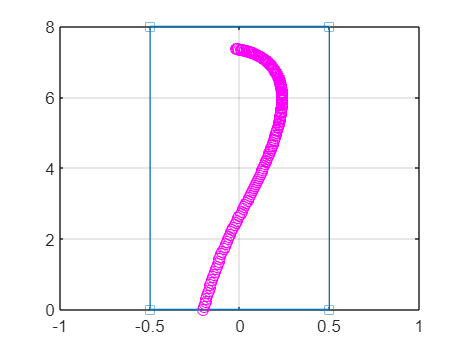

clear
clc
tspan = [0 10]; %anger tidsspannet 
v0 = 1.6; %utgångshastighet
n = 200; %antal mättpunkter i tidsintervallet
y0 = -0.2; %startposition
theta = 0.05; %startvinkel

[d1,d2] = drawField(); %ritar banan (1x8 meter)
[y,vy,ty] = yEuler(@yOde,tspan,y0,v0,n,theta); %kallar på euler som i sin tur tar in ODE
[x,vx,tx] = xEuler(@xOde,tspan,v0,n,theta);
[x1,vx1,y1,vy1] = calcStop(x,vx,y,vy,n+1); %Beräknar om slutpositionen

plot(d1,d2,'s -',y1,x1,'o m')
grid on
hold off

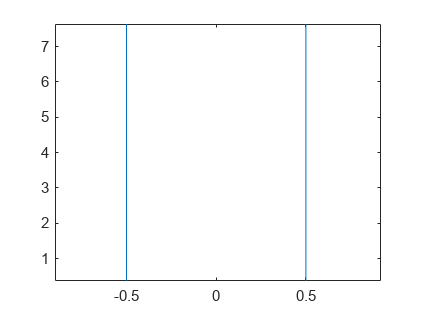

animation(x1,y1) %enkel animering av puckens rörelse.